syms H magX T k y D real positive
syms phaseX wt real
A = H/2;

%y = D/2;
% relevant y is from -D/2 to +D/2, 
% assuming WEC is centered at y=0 and 
% phaseX defines the phase of the center of the WEC.
eta = A * cos(wt - k*y);
X_zwaterline_WEC = magX * cos(wt + phaseX);
X_zbottom_WEC = X_zwaterline_WEC - T;
avoid_slamming = eta > X_zbottom_WEC

$$avoid\_slamming = \mathrm{magX}\,\cos\left(\mathrm{phaseX}+\mathrm{wt}\right)-T<\frac{H\,\cos\left(\mathrm{wt}-k\,y\right)}{2}$$

% gave up doing it in matlab and derived it by hand
% on notebook p40, % 12/26/24

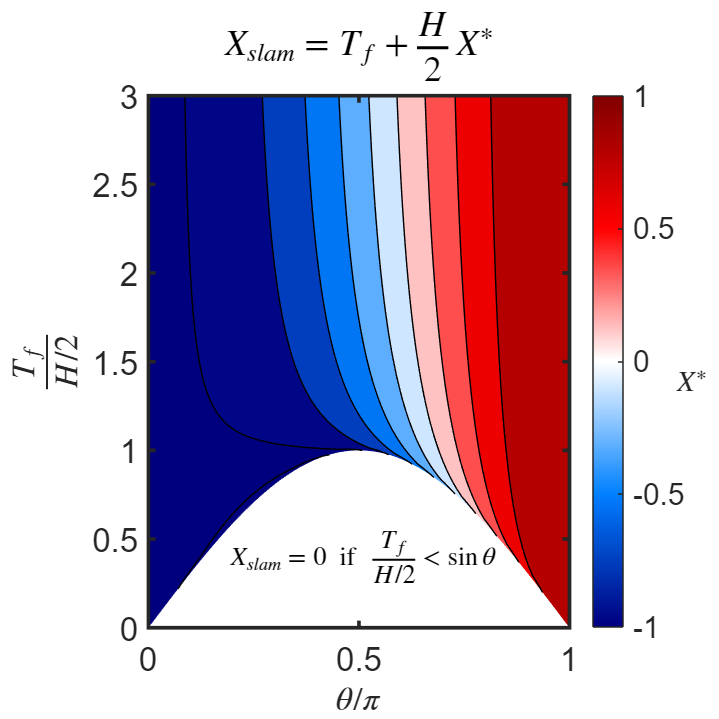

theta = linspace(0,pi,200);
T_f_over_H_span = linspace(0,1,120);
two_Tf_over_H_max = 3;
[THETA,TWO_TF_OVER_H_SPAN] = meshgrid(theta,T_f_over_H_span);

TWO_TF_OVER_H = sin(THETA) + TWO_TF_OVER_H_SPAN .* (two_Tf_over_H_max - sin(THETA));
squared = sin(THETA)./(TWO_TF_OVER_H);
X_map = TWO_TF_OVER_H .* (sqrt(1 - squared.^2) - 1) - cos(THETA);
idx_imag = X_map~=real(X_map);
X_map(idx_imag) = NaN;%-2*TF_OVER_H(idx_imag);

figure
contourf(THETA/pi,TWO_TF_OVER_H,real(X_map),10)
cb=colorbar;
clim([-1 1])
colormap(bluewhitered)
cb.Label.String = '$X^*$';
cb.Label.Interpreter = 'latex';
cb.Label.Rotation = 0;
cb.Label.FontSize = 16;
xlabel('$\theta/\pi$','Interpreter','latex','FontSize',14)
ylabel('$\frac{T_f}{H/2}$','Interpreter','latex','FontSize',14)
title('$X_{slam}=T_f+\frac{H}{2} X^*$','Interpreter','latex')
my_text = '$X_{slam}=0 ~\textrm{if}~ \frac{T_f}{H/2} < \sin\theta$';
text(.19,.4,my_text,'Interpreter','latex','FontSize',14)
improvePlot

X_map_2 = TWO_TF_OVER_H .* (sqrt(1 - squared.^2)) - cos(THETA);
idx_imag = X_map_2~=real(X_map_2);
X_map_2(idx_imag) = NaN;%-2*TF_OVER_H(idx_imag);

figure
contourf(theta/pi,T_f_over_H,real(X_map_2),10)

Unrecognized function or variable 'T_f_over_H'.

cb=colorbar;
cb.Label.String = 'X*';
xlabel('$\theta/\pi$','Interpreter','latex')
ylabel('$\frac{T_f}{H/2}$','Interpreter','latex')
%clim([-1 1])
title('$X_{slam}=H/2 X*$','Interpreter','latex')